# Influence of Cholesterol on Heart Disease (Binomial Sampling)

*Dr. Eric S. Wright*

*The University of Montana Western*

# 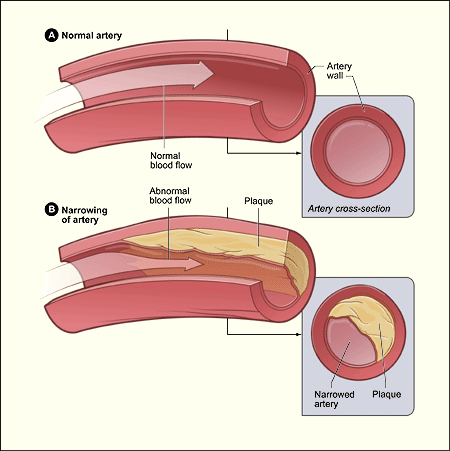

Atheroschlerosis - public domain image: https://simple.wikipedia.org/wiki/Arteriosclerosis#/media/File:Atherosclerosis_diagram.png

## Introduction

Heart disease is often linked to many different factors that are tied to lifestyle, genetics, physiology, etc. In this LiveScript, we develop a methodology for determining whether there is a significant relationship between a single factor (specifically: overall cholesterol) and the presence of heart disease. We base our work on the well-known, publicly available Cleveland data on heart disease in medical study subjects. 

This program has the following objectives:

- Load the external Cleveland data into a MATLAB table.

- Split the data into two sets: one for which test subjects have a cholesterol level in the normal range and one for which test subjects have high cholesterol. In this study, the high cholesterol group will serve as the experimental population and the normal cholesterol group will serve as the control population.

- Use the binomial framwork to sample groups of subjects (with replacement) from the control population and count the number within each sample that have heart disease. These counts constitute the control data set. Use a similar technique to build an experimental data set from the experimental population.

- Compute descriptive statistics of the control data. This will include several measures of central tendency, variability, asymmetry, and the importance of outliers.

- Produce several visualizations of the data including histograms and box and whisker plots.

- Fit a probability distribution (the binomial distribution in this case) to the data using parameter estimation and validate the fit of the model by comparing the relative frequency histogram of the data set to a bar graph of the theoretical distribution, comparing the empirical shape parameters of the data to the theoretical shape parameters of the distribution, examining a quantile-quantile plot, and performing Pearson's goodness of fit test

- Test the null hypothesis that there is no significant difference between the experimental data and the values our theoretical model for the control data leads us to expect.

- Test the null hypothesis that there is no significant difference between the mean of the experimental data and the expected mean of our theoretical distribution (or that there is no significant difference between the means of the control and experimental data sets).

- Test the null hypothesis that there is no significant difference between the variance of the experimental data and the expected variance of our theoretical distribution (or that there is no significant difference between the variances of the control and experimental data sets).

- Use bootstrap sampling methods and perform tests for differences between means based upon the bootstrap samples. 

## Data Collection and Wrangling

Clear all memory, close all figures, and clean out the command line history

clear all; close all; clc;

Since we will be sampling randomly from data sets, choose the seed for the random number generator for reproducibility. Disable this if you want to replicate this experiment multiple times.

rng(1);

Import the UCI Machine Learning Repository Cleveland data into a table. I used the processed.cleveland.data data set and saved it under the name "processed.cleveland.csv". The readtable command loads the data from the file into an internal MATLAB table. However, I need to manually set the names of the columns for this table. I obtain these names from the documentation UCI provided for the data set. The page for obtaining this data can be found here: [https://archive.ics.uci.edu/ml/datasets/heart+disease](https://archive.ics.uci.edu/ml/datasets/heart+disease)

VarNames={'age','sex','cp','trestbps','chol','fbs','restecg','thalach','exang','oldpeak','slope','ca','thal','num'};
cleveland_data=readtable('Data/processed.cleveland.csv');
cleveland_data.Properties.VariableNames=VarNames

cleveland_data = 303×14 table
    age    sex    cp    trestbps    chol    fbs    restecg    thalach    exang    oldpeak    slope    ca    thal    num
    ___    ___    __    ________    ____    ___    _______    _______    _____    _______    _____    __    ____    ___

    63      1     1       145       233      1        2         150        0        2.3        3      0      6       0 
    67      1     4       160       286      0        2         108        1        1.5        2      3      3       2 
    67      1

The data set contains more attributes than we really care about.  All we need to know is whether a subject has high cholesterol (>200mg/dl) and whether or not they have heart disease (measurable narrowing of the arteries (num>=1). We'll create a simplified data set that summarizes the membership of each subject in these two categories.

cleveland_data.high_chol=cleveland_data.chol>200

cleveland_data = 303×15 table
    age    sex    cp    trestbps    chol    fbs    restecg    thalach    exang    oldpeak    slope    ca    thal    num    high_chol
    ___    ___    __    ________    ____    ___    _______    _______    _____    _______    _____    __    ____    ___    _________

    63      1     1       145       233      1        2         150        0        2.3        3      0      6       0       true   
    67      1     4       160       286      0        2     

cleveland_data.heart_disease=cleveland_data.num>0

cleveland_data = 303×16 table
    age    sex    cp    trestbps    chol    fbs    restecg    thalach    exang    oldpeak    slope    ca    thal    num    high_chol    heart_disease
    ___    ___    __    ________    ____    ___    _______    _______    _____    _______    _____    __    ____    ___    _________    _____________

    63      1     1       145       233      1        2         150        0        2.3        3      0      6       0       

Our goal is to produce two separate data sets. The first will be created by randomly sampling 50 groups of 30 subjects each (with replacement) from the population that has normal cholesterol levels (at or below 200 mg/dl). These are the people with a 0 in the high_chol column. From each sample, we will count the number with heart disease. Each count represents a single data point in our first data set. Then, we'll randomly sample 50 more groups of 30 subjects each (again with replacement) from the population that has high cholesterol levels. We'll produce similar counts for them.

N_control=50

N_control = 50

N_experimental=50

N_experimental = 50

normal_chol_idx=~(cleveland_data.high_chol);
high_chol_idx=cleveland_data.high_chol;
ControlData=zeros(1,N_control);
ExperimentalData=zeros(1,N_experimental);
for i=1:N_control
    normal_chol_hd_sample=randsample(cleveland_data.heart_disease(normal_chol_idx),30,true);
    ControlData(i)=sum(normal_chol_hd_sample);
end
ControlData

ControlData =     14    15    11    13     9    16    15     8    15    11    10    12    14    12    13    10    15     8    10    10    11    10    14    13    11    10    16     9    12    10    12    10    17    11    15    19    13    15    12    14     8    16    13    13    17    13    14    17    12    15



for i=1:N_experimental
    high_chol_hd_sample=randsample(cleveland_data.heart_disease(high_chol_idx),30,true);
    ExperimentalData(i)=sum(high_chol_hd_sample);
end
ExperimentalData

ExperimentalData =     13    11    13    19    16    13    12    14    16    11    13    15    17    11    13    17    15    13    10    14    15     8    17    12     9    16    16    11    14    12    14    12    18    14    12    11    15    10    14    18    10    13    13    14    14    16    18    13    18    17


At this point, we have two data sets. The first, ControlData, represents the number of people among samples of 30 drawn from the normal cholesterol population who also have signs of heart disease. The second, ExperimentalData, represents the number of people among samples of 30 drawn from the high cholesterol population who also have signs of heart disease. Next, we'll proceed to compute a variety of descriptive statistics from and construct visualizations for the first data set so that we may compare the values from the second data set to them.

## Descriptive Statistics

Summarize the basic, descriptive statistics for the control data set.

ds=STAT121utils.descriptiveStats(ControlData)

ds = struct with fields:
         Mean: 12.6600
       Median: 13
         Mode: 10
          Max: 19
          Min: 8
        Range: 11
       StdDev: 2.6200
     Variance: 6.8644
    Quartiles: [10 13 15]
          IQR: 5
     Skewness: 0.1524
       Bowley: -0.2000
     Kurtosis: 2.3314


## Visualizations

A histogram summarizes the frequencies of each value found in the control data set.

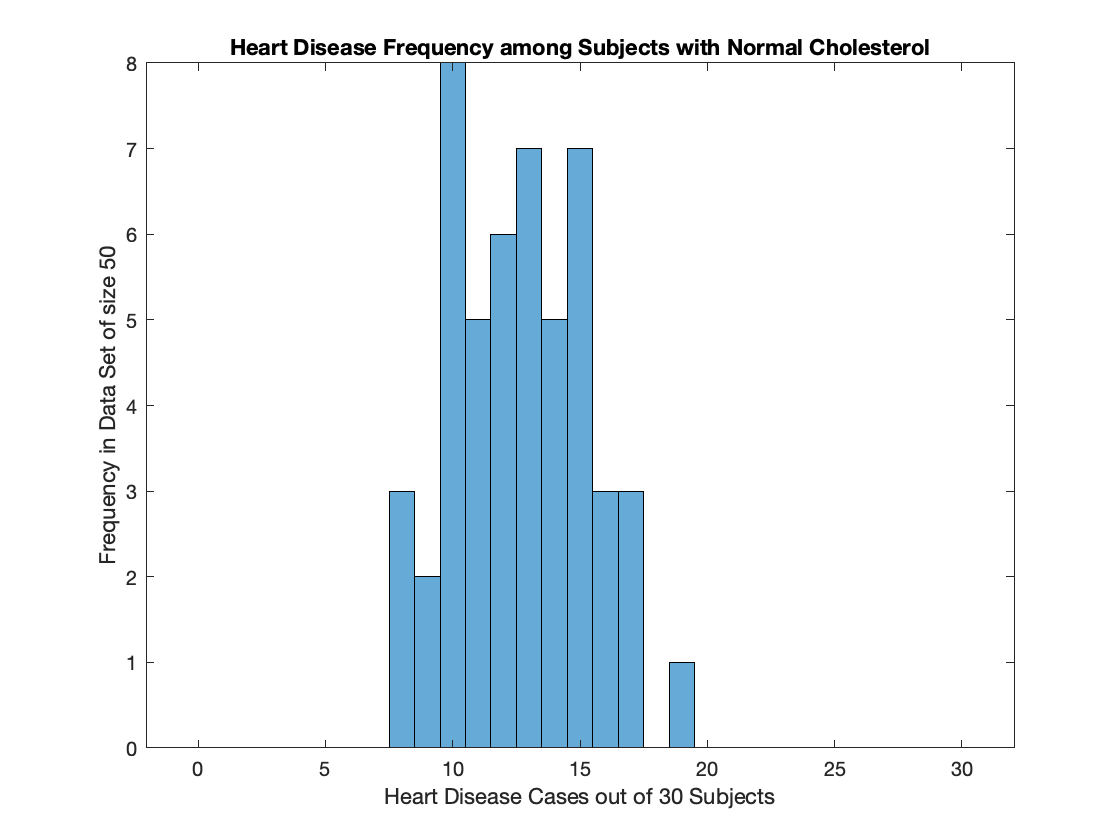

figure(1)
histogram(ControlData,-0.5:1:30.5)
title("Heart Disease Frequency among Subjects with Normal Cholesterol")
xlabel("Heart Disease Cases out of 30 Subjects")
ylabel("Frequency in Data Set of size 50")

A box and whisker plot summarizes the quartiles and outliers of the control data set.

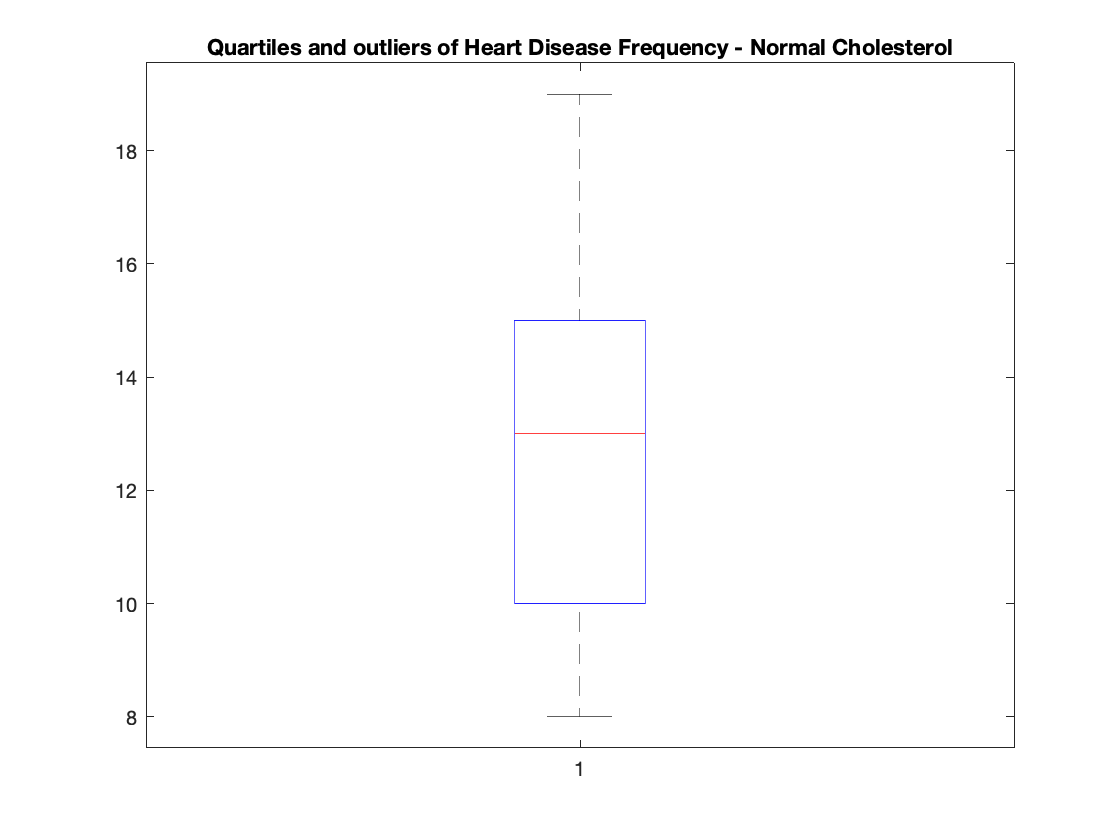

figure(2)
boxplot(ControlData)
title("Quartiles and outliers of Heart Disease Frequency - Normal Cholesterol")

## Parameter Estimation

### Maximum Likelihood Estimation

MATLAB has a built in maximum likelihood estimation function (mle). We can use it to perform parameter estimation for many of the common probability distributions. 

n=30;
p=mle(ControlData,"distribution","Binomial","NTrials",n)

p = 0.4220

Alternatively, we can just form the negative log-likelihood function ourselves, and minimize it using fminbnd() (for continuous parameters). The results are the same.

myLikelihood=@(pstar) sum(-log(binopdf(ControlData,n,pstar)))

myLikelihood = function_handle with value:
    @(pstar)sum(-log(binopdf(ControlData,n,pstar)))


p2=fminbnd(myLikelihood,0,1);

### Validation

Create a binomial distribution object that we calibrate with our values of $n$ and $p$.

pd=makedist("Binomial","N",n,"p",p);

Build the arrays of observed frequencies from the control data set and expected frequencies from the theoretical distribution. Compare these frequencies with a side-by-side bar graph.

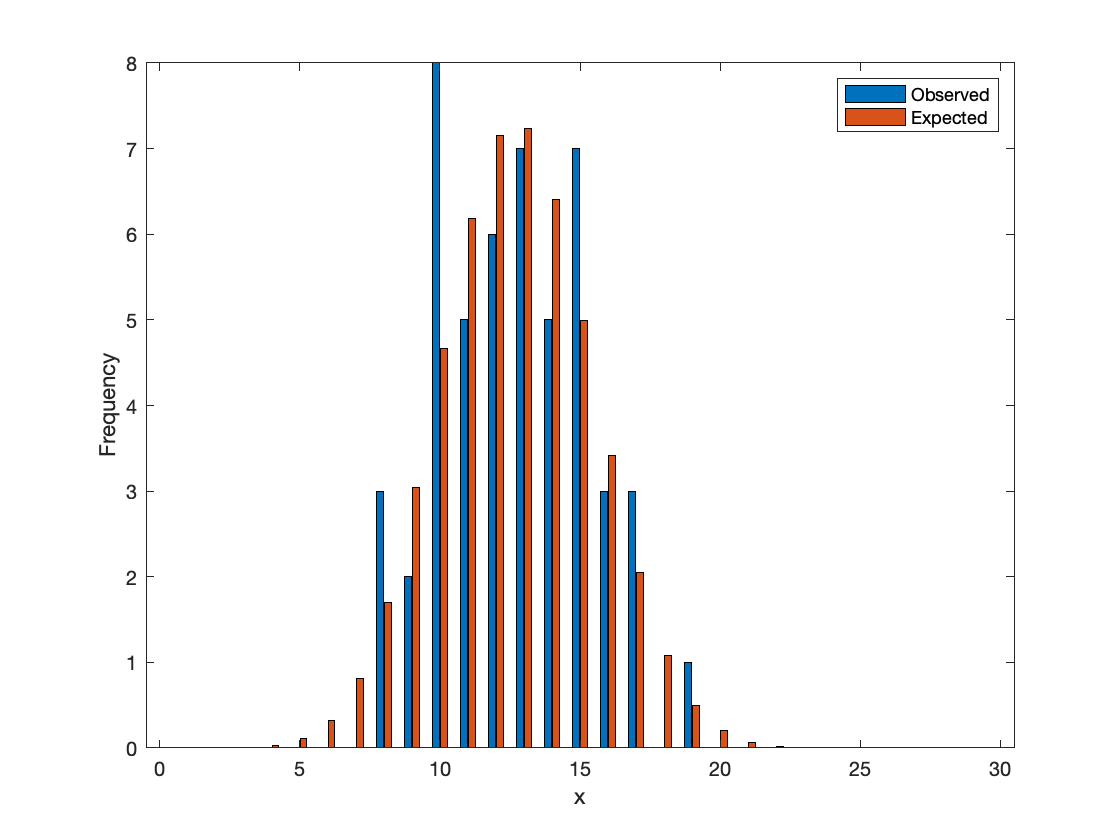

figure(3)
[ObservedFrequencies,ExpectedFrequencies]=STAT121utils.frequencyPlot(ControlData,pd);

Compute and compare the empirical and theoretical shape parameters.

shapes=STAT121utils.compareShapeParameters(ControlData,pd)

shapes = 2×4 table
                   MEAN     VARIANCE    SKEWNESS    KURTOSIS
                   _____    ________    ________    ________

    Empirical      12.66     6.8644      0.15241     2.3314 
    Theoretical    12.66     7.3175     0.057669     2.9367 


Construct a quantile-quantile plot that compares the quantiles of the control data set to the corresponding quantiles of the theoretical distribution

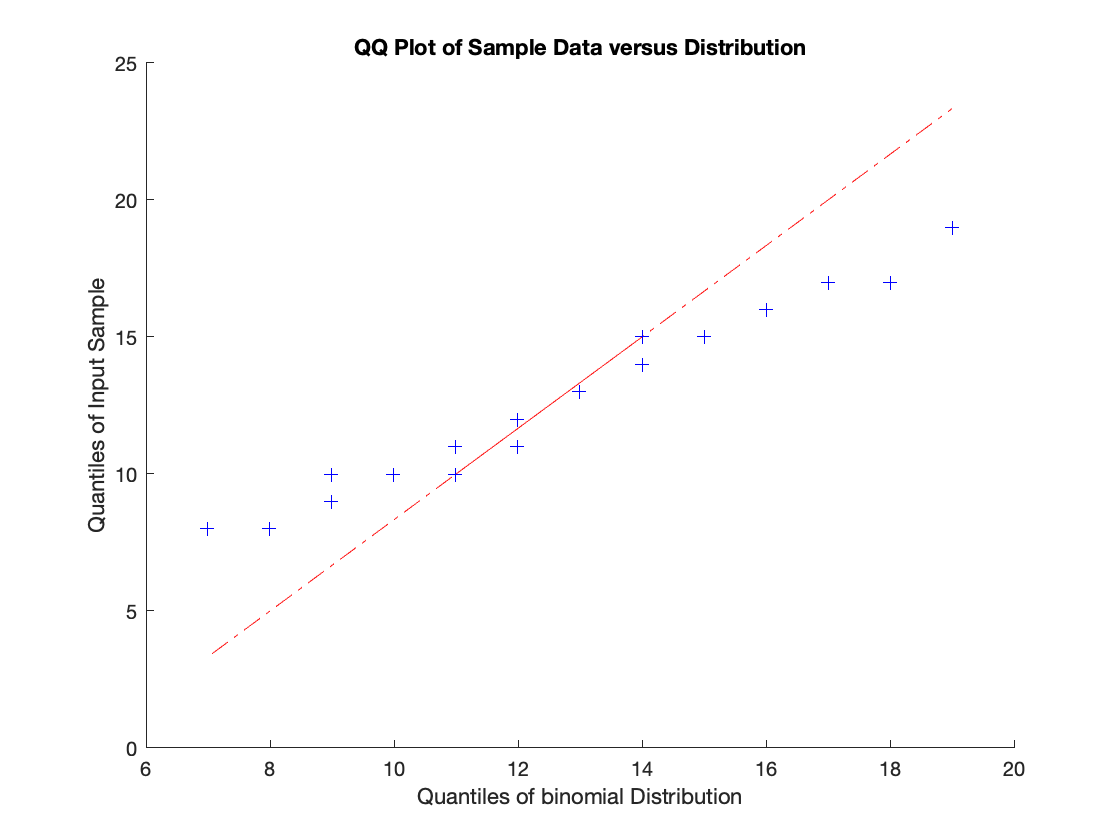

figure(4)
qqplot(ControlData,pd)

Finally, perform Pearson's goodness of fit test.

[h,pChi2,stats]=chi2gof(ControlData,'CDF',@pd.cdf,"NParams",1)

h = 0

pChi2 = 0.8343

stats = struct with fields:
    chi2stat: 1.4567
          df: 4
       edges: [8.0000 10.2000 11.3000 12.4000 13.5000 14.6000 19.0000]
           O: [13 5 6 7 5 14]
           E: [10.6800 6.1865 7.1516 7.2296 6.4095 12.3428]


% Reverse engineering what's actually going on here.
edges=[-1 10 11 12 13 14 30]

edges =     -1    10    11    12    13    14    30


EXP=binocdf(edges,30,p);
EXP=50*(EXP(2:end)-EXP(1:end-1))

EXP =    10.6800    6.1865    7.1516    7.2296    6.4095   12.3428


## Hypothesis Testing

### Fisher's Significance Testing

#### Binomial Test 

Since we were able to establish such strong validation for the fit between the binomial model and our control data, we are justified in conducting the binomial tests for differences between experimental data and behavior predicted by the model. The null hypothesis for this test is

$H_0$: *We will not observe significantly different numbers of test subjects with heart disease in the high cholesterol group compared to what the binomial model for the normal cholesterol group leads us to expect.*

The p values resulting from the geometric test are computed as follows.:

[pIncreaseDiscrete,pDecreaseDiscrete]=STAT121utils.discreteSignificance(ExperimentalData,pd)

pIncreaseDiscrete =     0.5196    0.7864    0.5196    0.0159    0.1470    0.5196    0.6627    0.3750    0.1470    0.7864    0.5196    0.2469    0.0787    0.7864    0.5196    0.0787    0.2469    0.5196    0.8796    0.3750    0.2469    0.9745    0.0787    0.6627    0.9404    0.1470    0.1470    0.7864    0.3750    0.6627    0.3750    0.6627    0.0376    0.3750    0.6627    0.7864    0.2469    0.8796    0.3750    0.0376    0.8796    0.5196    0.5196    0.3750    0.3750    0.1470    0.0376    0.5196    0.0376    0.0787


pDecreaseDiscrete =     0.6250    0.3373    0.6250    0.9940    0.9213    0.6250    0.4804    0.7531    0.9213    0.3373    0.6250    0.8530    0.9624    0.3373    0.6250    0.9624    0.8530    0.6250    0.2136    0.7531    0.8530    0.0596    0.9624    0.4804    0.1204    0.9213    0.9213    0.3373    0.7531    0.4804    0.7531    0.4804    0.9841    0.7531    0.4804    0.3373    0.8530    0.2136    0.7531    0.9841    0.2136    0.6250    0.6250    0.7531    0.7531    0.9213    0.9841    0.6250    0.9841    0.9624


sum(pIncreaseDiscrete<0.05)

ans = 5

sum(pDecreaseDiscrete<0.05)

ans = 0

Here, several of the p values from the test for an increase fall below 5%. While it is not a majority, there is still a surprising number of significant results. We may not be justified in fully rejecting the null hypothesis, but we should consider studying the problem in more depth.

#### One Sample T-Test

The good fit between the binomial model and the control data also provides justification for conduct a one sample t test for differences between the mean of the experimental set and the theoretical mean predicted by the binomial distribution. This is a good, alternative test for us to perform given the inconclusive nature of the results from our binomial test. The null hypothesis for this test is

$H_0$*: There is no significant difference between the mean of the experimental data set and the theoretical mean predicted by the binomial distribution. *

This test can be performed as follows:

[h,pt,ci,stats]=ttest(ExperimentalData,pd.mean)

h = 1

pt = 0.0031

ci =    13.0625   14.5375


stats = struct with fields:
    tstat: 3.1062
       df: 49
       sd: 2.5951


The p value (pt) for this test is smaller than 5%. This provides evidence for rejecting the null hypothesis that the theoretical mean and mean of the experimental sample are the same. The ttest function also provides us with a 95% confidence interval that establishes the location of the true mean for the population that the experimental data is taken from.

#### Two Sample T Test

Alternatively, we could address the slightly different task of determining if there is a difference between the means of the control and experimental data sets by conducting the two sample t test. Before doing so, it is worth investigating the similarity between the control and experimental variances, because this can impact how we design our two sample T test. There are two approaches we can follow:

First, since we know the binomial distribution fits our control data well, we are justified in conducting the $\chi^2$ test for differences between the sample variance of our experimental data set and our theoretical variance predicted by the binomial distribution. The null hypothesis for the $\chi^2$ test is

$H_0$*: There is no significant difference between the variance of the experimental data and the theoretical variance predicted by the binomial distribution.*

and we may perform the test as follows:

[h,pvar,ci,stats]=vartest(ExperimentalData,pd.var)

h = 0

pvar = 0.7359

ci =     4.6994   10.4580


stats = struct with fields:
    chisqstat: 45.0975
           df: 49


We can se that the p vlaue is too high to reject the null hypothesis that there is no difference between the variances. The $\chi^2$ test also supplies a 95% confidence interval for the true variance of the population the experimental data was sampled from.

If we had been unable to establish such a good fit between our binomial model and our control data, we could alternatively investigate similarities between the variances of the populations the experimental and control data sets were sampled from by conducting the F test. While this is unnecessary in our particular case, we'll still perform it. The null hypothesis for this test is

$H_0$*: There is no significant difference between the variance of the experimental data set and the variance of the control data set. *

We perform the test as follows:

[h,pvar2,ci,stats]=vartest2(ExperimentalData,ControlData)

h = 0

pvar2 = 0.8912

ci =     0.5456    1.6943


stats = struct with fields:
    fstat: 0.9615
      df1: 49
      df2: 49


Again, the p value is too high to justify rejecting the null hypothesis that there is no difference between the variance. The F test also supplies a 95% confidence interval for the true ratio between the variances of the experimental and control populations.

Both tests allow us to assume that the experimental and control variances are at least somewhat similar. However, the confidence intervals we've computed are also somewhat large, so there is some uncertainty surrounding this assumption. While we are probably still justified in performing the two sample t test with an equal variance assumption in place, it would be more conservative of us to drop that assumption. 

The null hypothesis for the two sample t test (without an assumption of equal variances between the experimental and control samples) is 

$H_0$*: There is no significant difference between the means of the experimental and control data sets.* 

This test bypasses the need of knowing that the binomial distribution is the model for our original counts of test subjects in our sample with heart disease and having access to the theoretical mean of that distribution. We simply treat our control and experimental data sets as two independent samples (with potentially different sample variances) and test for equality of the two sample means. This would have been an appropriate choice of a hypothesis test for determining differences between our experimental and control measurements had we been unable to achieve a strong fit between our binomial model and the control data. While it is somewhat unnecessary in our case, we may perform this test as follows:

[h,pt2,ci,stats]=ttest2(ExperimentalData,ControlData,'Vartype',"unequal")

h = 1

pt2 = 0.0321

ci =     0.0997    2.1803


stats = struct with fields:
    tstat: 2.1748
       df: 97.9622
       sd: [2.5951 2.6466]


Again, we have a small p value (pt2) that justifies rejecting the null hypothesis that the means of the experimental and control samples are the same. The ttest2 function also provides us with a 95% confidence interval that establishes the location of the difference between the true means for the populations that the experimental and control data is taken from.

### Bootstrap Confidence Interval

Simulate 2000 samples of 40 data points from the control data set and compute their means. This set of means is a bootstrap data set.

B=2000;
bootstrapMeans=bootstrp(B,@mean,ControlData);

Compute a 95%, two-tailed confidence interval from the bootstrap data set by locating its 2.5 and 97.5 percentiles. Determine where the mean of the experimental data set falls relative to the confidence interval.

CI=quantile(bootstrapMeans,[0.025 0.975])

CI =    11.9600   13.3600


Me=mean(ExperimentalData)

Me = 13.8000

Visualize the confidence interval and experimental mean on top of the bootstrap data set.

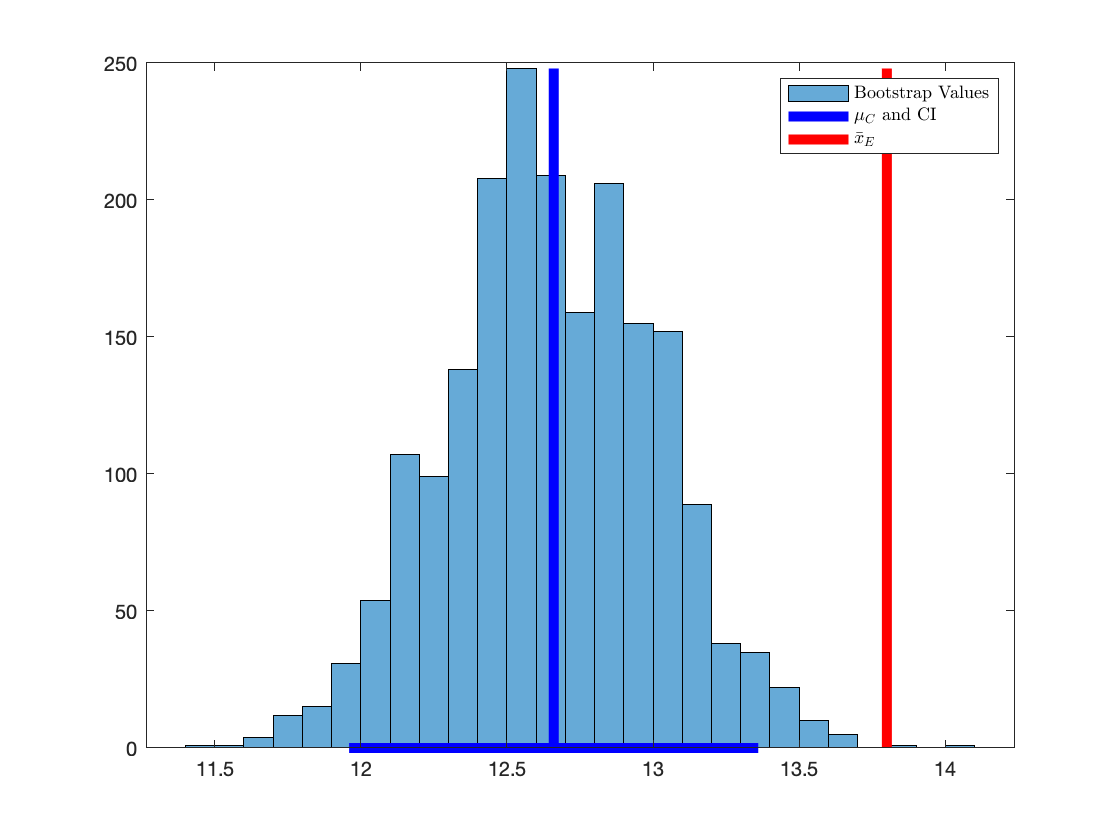

figure(5)
h=histogram(bootstrapMeans);
hold on
plot(CI,[0,0],'b','LineWidth',5)
plot([Me,Me],[0,max(h.BinCounts)],'r','LineWidth',5)
plot([pd.mean,pd.mean],[0,max(h.BinCounts)],'b','LineWidth',5)
legend('Bootstrap Values','$\mu_C$ and CI', '$\bar{x}_E$', 'interpreter','Latex')
hold off

We can see that the mean of our experimental data set falls well outside the bootstrap confidence interval. This is an indication that the mean of our experimental data set is different from what we expect to see in typical control data.

#### Bootstrap Two Sample Test

We can also create a bootstrap sample from our experimental data set. This has the potential to give us a better picture of what might happen should we repeat our experiment multiple times. 

Create 2000 bootstrap samples from both the control and experimental data sets. The size of each sample taken from the control data set should mirror the size of the control data set. The size of each sample taken from the experimental data set should mirror the size of the experimental data set. For each sample, track the sample means and sample standard deviations as well as the two sample t statistic (that makes no assumption about similarity between control and sample variances).

B=2000;

Nc=length(ControlData);
Ne=length(ExperimentalData);
xbar=mean(ControlData);
ybar=mean(ExperimentalData);
zbar=mean([ControlData ExperimentalData]);

statsc=bootstrp(B,@(x)[mean(x),std(x)],ControlData'-xbar+zbar);
statse=bootstrp(B,@(x)[mean(x),std(x)],ExperimentalData'-ybar+zbar);
Mc=statsc(:,1);
Sc=statsc(:,2);
Me=statse(:,1);
Se=statse(:,2);
t=(Me-Mc);
t=t./sqrt((Se.^2/Ne)+(Sc.^2/Nc));


Compare the histograms of the two bootstrap data sets.

figure(6)
CIc=quantile(Mc+xbar-zbar,[0.025,0.975])

CIc =    11.9400   13.3600


CIe=quantile(Me+ybar-zbar,[0.025,0.975])

CIe =    13.0800   14.5600


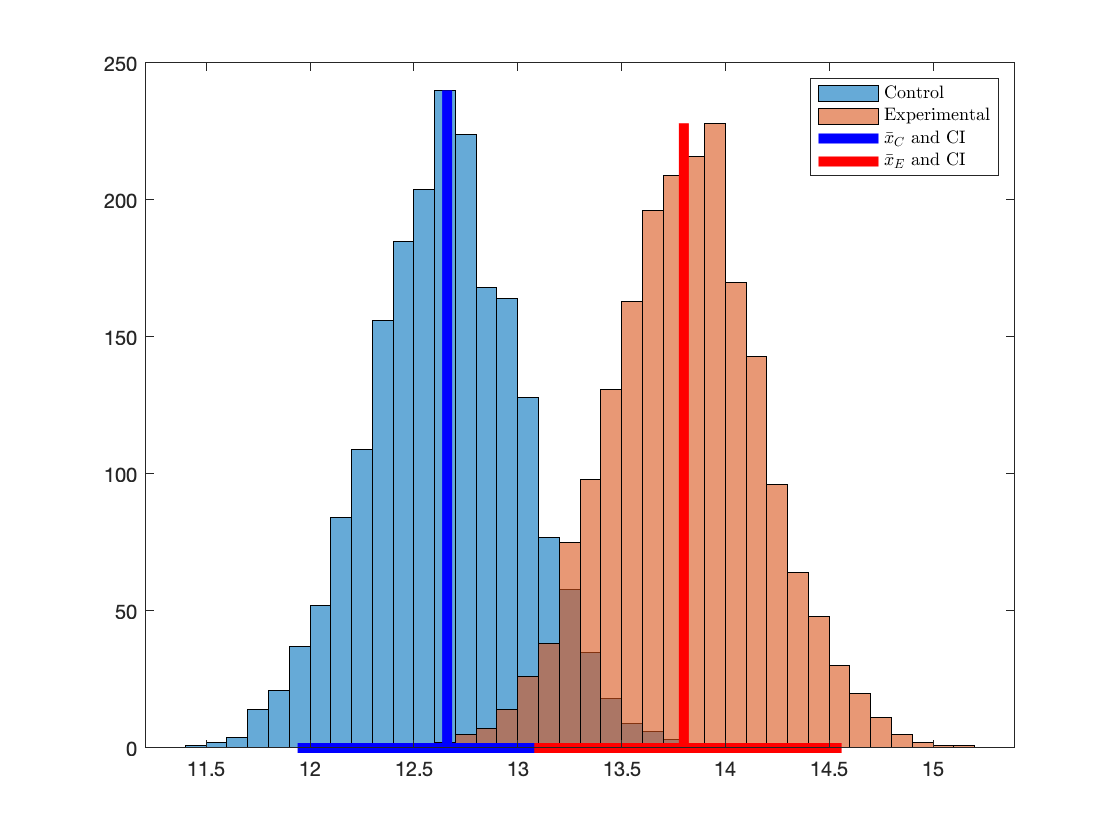


hc=histogram(Mc+xbar-zbar);
hold on 
he=histogram(Me+ybar-zbar);
plot(CIc,[0,0],'b','LineWidth',5)
plot(CIe,[0,0],'r','LineWidth',5)
plot([xbar xbar],[0,max(hc.BinCounts)],'b',"LineWidth",5)
plot([ybar ybar],[0,max(he.BinCounts)],'r',"LineWidth",5)
legend('Control','Experimental','$\bar{x}_C$ and CI', '$\bar{x}_E$ and CI','interpreter','latex')
hold off

There appears to be very little overlap between the bootstrap distributions as well as the two confidence intervals. Additionally, the two sample means appear to well separated. All of this indicates that there is a difference between the two sample means, but we should determine this using more quantitative methods as well. Since we have a bootstrapped data set of two-sample t statistics, we can perform the analog of a two sample t test by computing the Achieved Significance Level (ASL) for testing whether the t statistic ($t_0$) for the experimental and control samples is significantly different from what we expect of t statistics computed from bootstrap samples that have been shifted to share a common mean. The ASL represents the percentage of bootstrapped t statistics for which $t\ge t_0$. We can use it lieu of the p-value from the two sample t-test.

t0=stats.tstat;
ASLboot=sum(t>=t0)/B

ASLboot = 0.0135

This value is small enough to quantitatively suggest that there is a significant difference between the two sample means.